clear
load('data.mat')

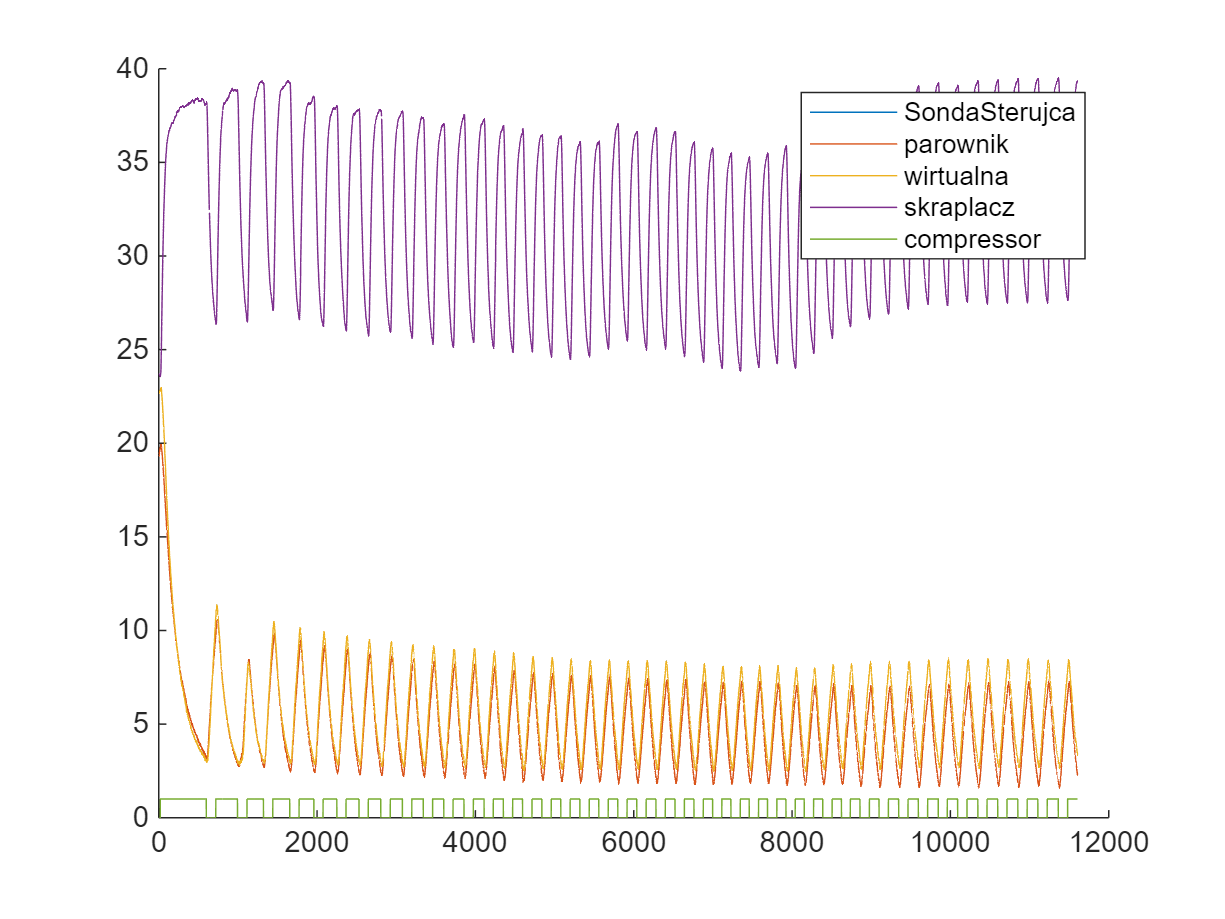

figure;hold on;
plot(data.SondaSterujca)
plot(data.parownik)
plot(data.wirtualna)
plot(data.skraplacz)
plot(data.compressor)
hold off

legend('SondaSterujca','parownik','wirtualna',...
'skraplacz','compressor')

Data filtering

% Find indices of NaN values
nan_indices = isnan(data.wirtualna);

% Exclude NaN values from the vector
wirualna = data.wirtualna(~nan_indices);

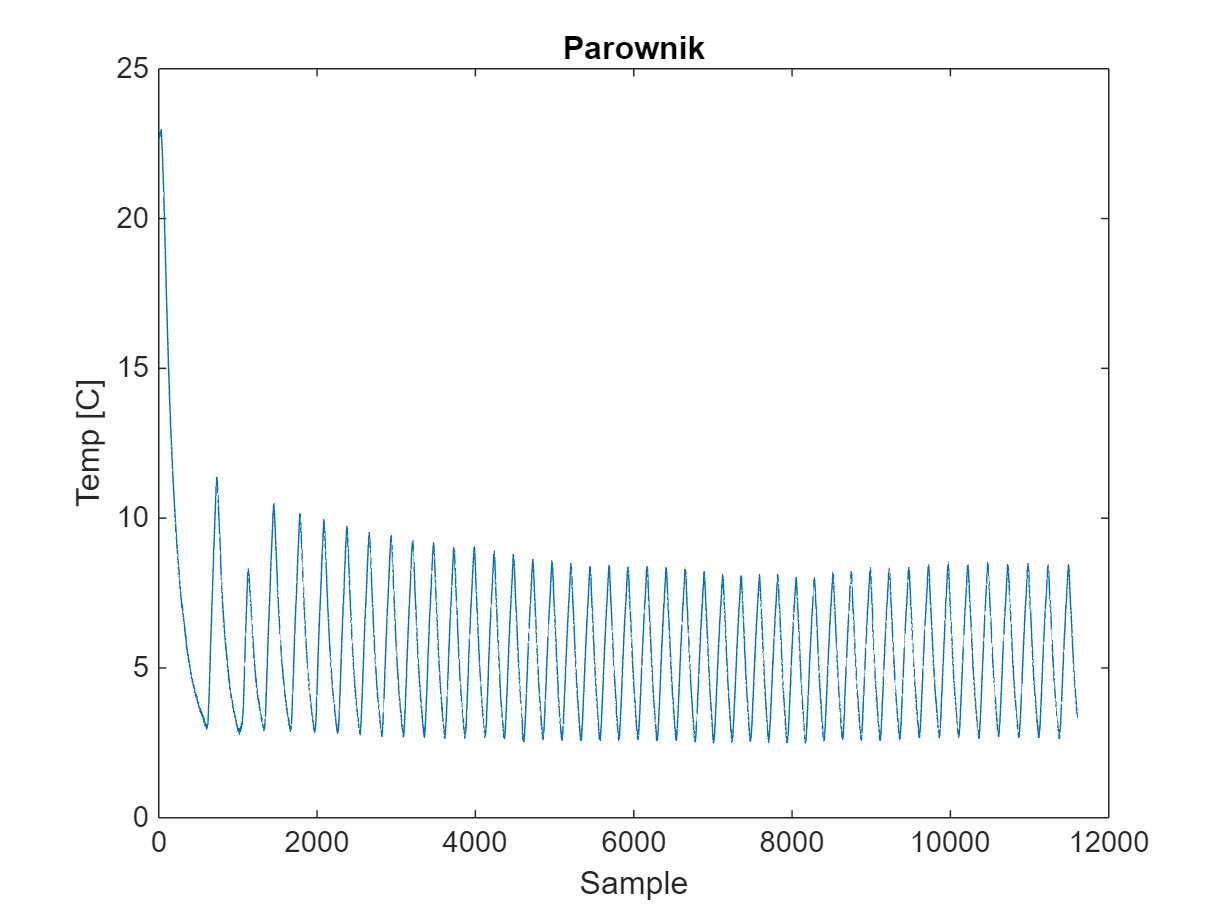

plot(wirualna)
title('Parownik')
xlabel('Sample')
ylabel('Temp [C]')

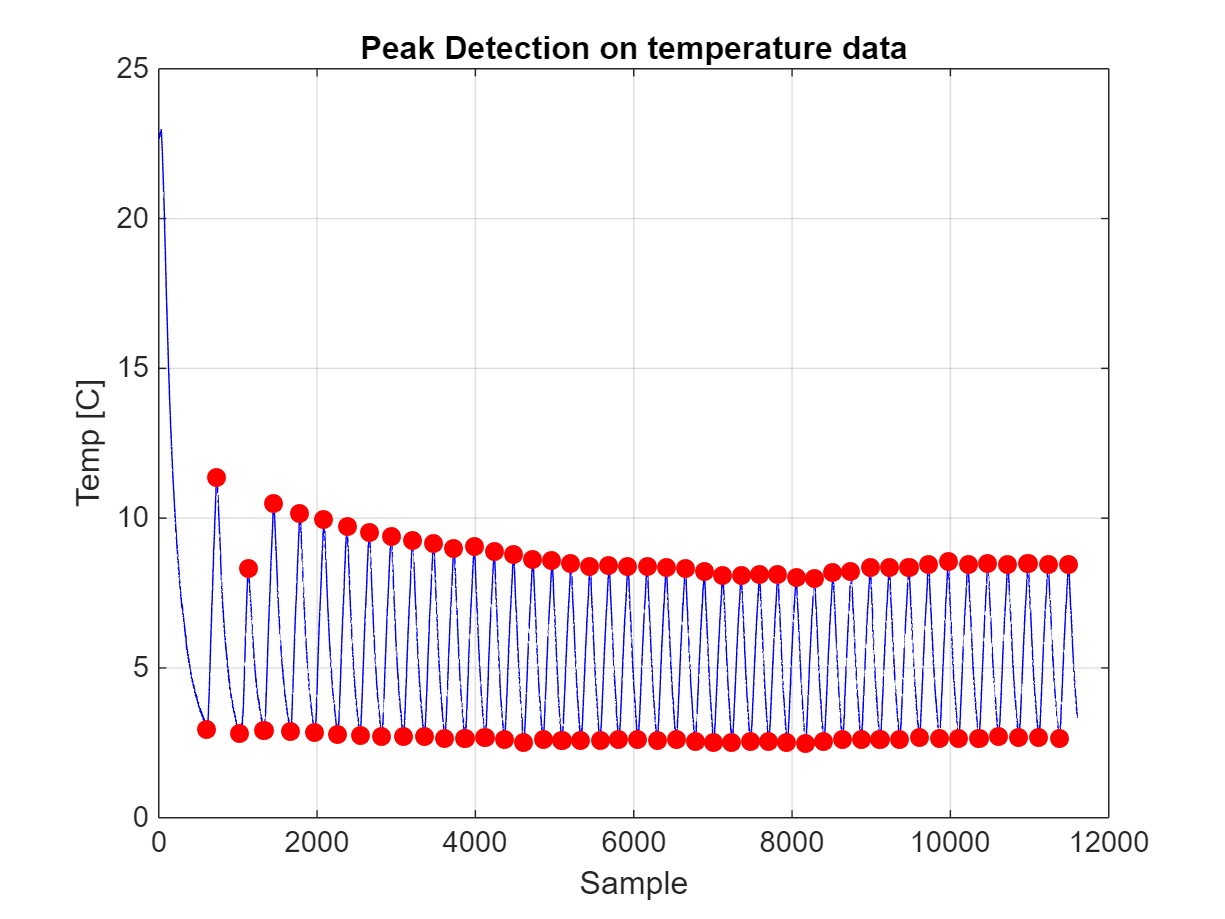

x=wirualna';
% Find peaks
[pks, locs_peaks] = findpeaks(x, ...
    'MinPeakProminence', 0.8, ...   % Ignore small peaks (noise)
    'MinPeakDistance', 0.17);        % Enforce minimum spacing (seconds)
% Find valleys
[valleys, locs_valleys] = findpeaks(-x, ...
    'MinPeakProminence', 0.8, ...   % Ignore small peaks (noise)
    'MinPeakDistance', 0.17);        % Enforce minimum spacing (seconds)
valleys=-valleys;
% Plot results
figure;
plot(x, 'b'); hold on;
plot(locs_peaks, pks, 'ro', 'MarkerFaceColor', 'r');
plot(locs_valleys, valleys, 'ro', 'MarkerFaceColor', 'r');

xlabel('Sample');
ylabel('Temp [C]');
title('Peak Detection on temperature data');
grid on; hold off

Peak-Valleys detection based compressor prediction:

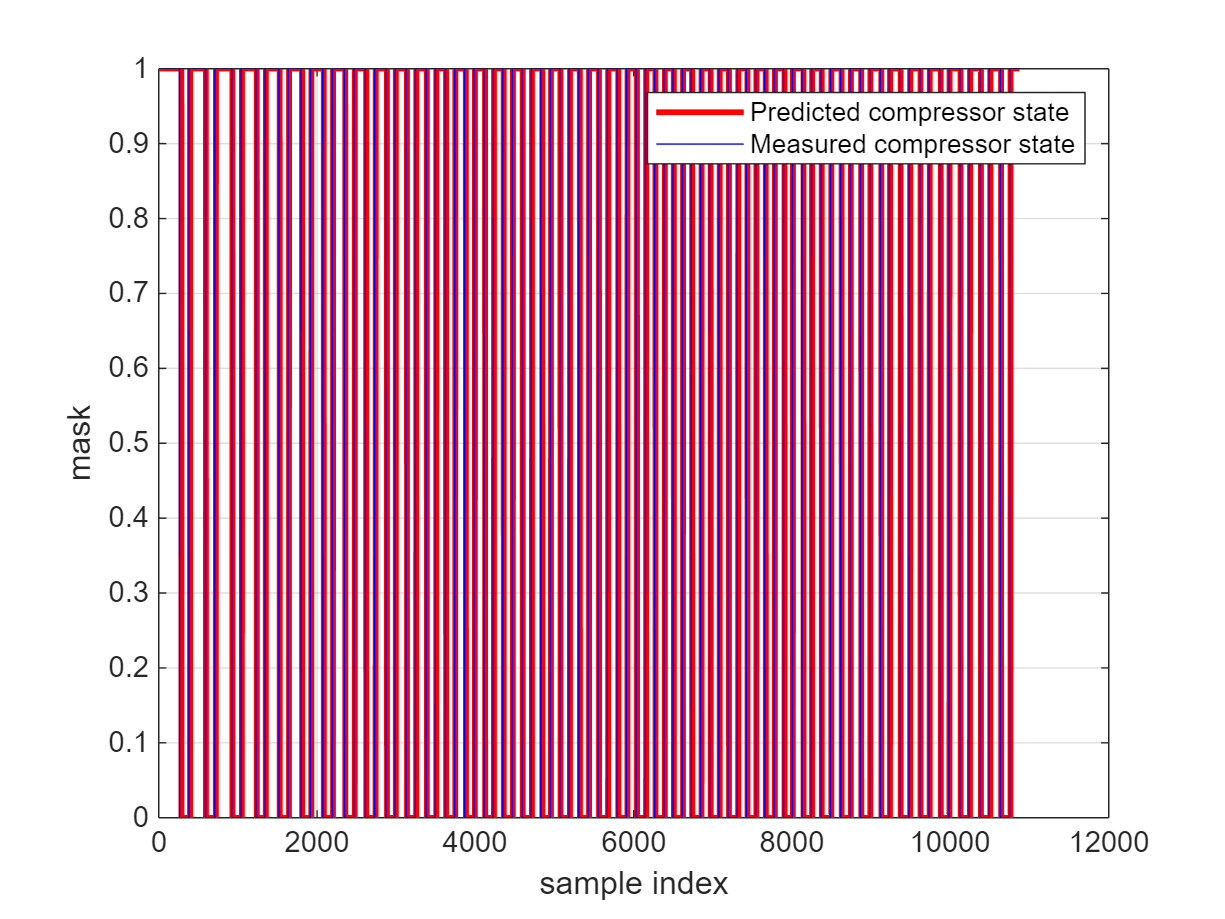

N=length(x);
mask = peakValleyMask(locs_peaks,locs_valleys,N);

% plot to check
t = 1:N;
plot(mask(locs_peaks(1):end),'-','LineWidth',2,'Color','r');hold on
plot(data.compressor(locs_peaks(1):end), 'b'); hold off;
grid on
xlabel 'sample index', ylabel 'mask'
legend('Predicted compressor state',"Measured compressor state")

mask_pred=mask(locs_peaks(1):end);
mask_meas=data.compressor(locs_peaks(1):end)';
mask_meas=mask_meas(1:length(mask_pred));
% compare
stats = compareOnTime(mask_pred, mask_meas);

% display
fprintf('Measured ON‐time = %.1f h\n', stats.timeOnMeas/3600);

Measured ON‐time = 1.6 h


fprintf('Predicted ON‐time= %.1f h\n', stats.timeOnPred/3600);

Predicted ON‐time= 1.7 h


fprintf('Difference      = %+0.1f s  (%.1f%%)\n',...
        stats.diffTime, stats.pctError);

Difference      = +72.0 s  (1.2%)
